# Señales y sistemas

## Explicacion: function handle vs Symbolic.



syms t
y_1=cos(t)
%fplot es para funciones simbolicas.
figure
fplot(y_1,[0,10])
%tambien se puede usar "function handle".
y_2= @(t) cos(t)
figure 
fplot(y_2,[0,10])
%Diferencias entre variables simbolicas y function handle.
y_2([5,10,8]) %Se evaluan directamente.
subs(y_1,t,[5,10,8]) %Error, no se evaluan directamente, se utiliza function subs().
%Ventaja simbólicas: Se puede hacer algebra con variables simbólicas.
%Con function handle no se puede hacer algebra.
y_3=y_1+sin(t)+exp(-t)
diff(y_3)
int(y_3,[0,1])

## Ejercicio: Continuas vs discretas.

t_dsc=0:10; %para que no aparezca el valor, al correr el programa, se usa el símbolo ";"
y_dsc=y_2(t_dsc);
figure
%plot se utiliza en este caso, para muestras y vectores.
plot(y_dsc)

%stem para "stem and leaf plot"
stem(y_dsc)
hold on
stem(t_dsc,y_dsc)
hold off
legend("Sin especificar t","Especificando t")

t_dsc=0:0.1:10;
y_dsc=y_2(t_dsc);          
figure
fplot(y_2,[0,10])        %grafica de funcion continua cos(t).
hold on
stem(t_dsc,y_dsc)        %grafica cos[n] para valores discretos.
hold off
legend("continua x(t)","discreta x[n]")

syms t
y_1=3*exp(0.40*t);         %se define la funcion x(t)
y_2=2*exp(-0.9*t);        %se define la funcion y(t)
figure
fplot(y_1,[-2,5])
hold on
fplot(y_2,[-2,5])
hold off
legend("x(t)","y(t)")

syms t
a=3
b=2
y_3=(a*cos(t)+b*sin(3*t))  %funcion general a*sin(t)+b*cos(t).

figure
fplot(y_3,[0,19])

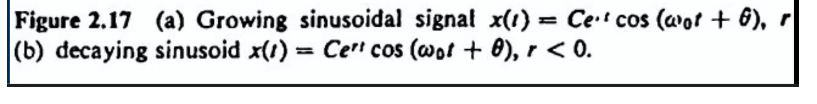

syms t
C=1;
o_0=100;
q=5;
r=-1
y_t=C*exp(r*t)*cos(o_0*t+q);
figure
fplot(y_t,[0,1])


Gráfica de la función seno:

t=0:0.1:100

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


x_t=sin(t)

x_t =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


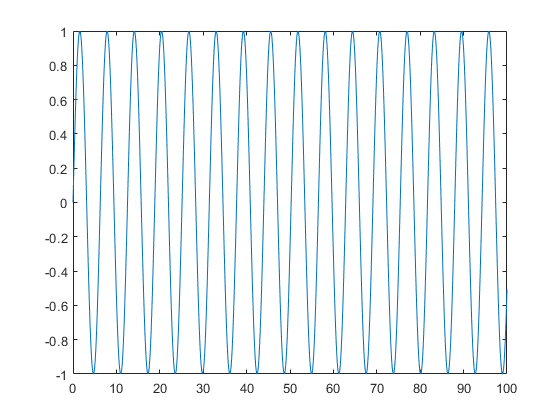

plot(t,x_t)


t=0:0.1:100

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y_t=exp(1)*cos(t)

y_t =     2.7183    2.7047    2.6641    2.5969    2.5037    2.3855    2.2435    2.0791    1.8938    1.6897    1.4687    1.2330    0.9850    0.7271    0.4620    0.1923   -0.0794   -0.3502   -0.6176   -0.8788   -1.1312   -1.3723   -1.5997   -1.8111   -2.0044   -2.1777   -2.3293   -2.4575   -2.5612   -2.6393   -2.6911   -2.7159   -2.7136   -2.6842   -2.6280   -2.5456   -2.4376   -2.3054   -2.1501   -1.9733   -1.7768   -1.5625   -1.3327   -1.0895   -0.8354   -0.5730   -0.3049   -0.0337    0.2378    0.5070


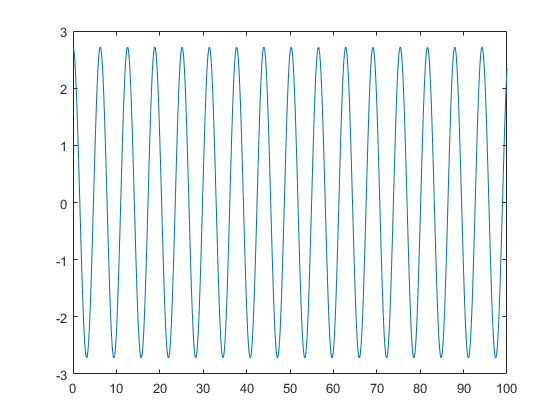

plot(t,y_t)